clear; clc;

## Parameters

trace = 0.05;
jitter_factor = 0.01;
folder = '/Volumes/My Book/data/Project Data/2024 - SA - WUS Temp Drought/';
Varnames = {'pr', 'tasmax', 'tasmin', 'vp', 'sfcWind', 'rsds', 'mrso', 'mrsos'}; nv = length(Varnames);
load([folder, 'result_240508_01_gldas_input_WUS_1deg_1948-2023.mat'], 'mask'); mask_sm = mask;
load('result_240508_01_cpc_input_WUS_1deg_1948-2023.mat', 'lon', 'lat', 'mask'); mask_pr = mask;
nlon = length(lon); nlat = length(lat);

## Load model data and perform bias correction

% run VP again
for i = 1% : nv
    % load observation data
    vartype = 0;
    jitter_factor = 0.01;
    if i == 1 % CPC precipitation
        load('result_240508_01_cpc_input_WUS_1deg_1948-2023.mat', 'pr');
        obs1 = reshape(pr(:,:,:,1:52), nlon*nlat, []); % use 1948-1999 data for reference
        vartype = 1; mask = mask_pr; jitter_factor = 0.001;
    elseif i>=2 && i<=6 % ERA5 temperature (max & min), vapor pressure, wind speed, solar radiation
        load('result_240508_01_era5_input_WUS_1deg_1940-2023.mat', 'vars');
        obs = vars{i-1}; mask = mask_pr;
        obs1 = reshape(obs(:,:,:,9:60), nlon*nlat, []); % use 1948-1999 data for reference
    else % GLDAS column and surface soil moisture
        load([folder, 'result_240508_01_gldas_input_WUS_1deg_1948-2023.mat'], 'sm_c', 'sm_s');
        mask = mask_sm;
        if i == 7
            obs1 = reshape(sm_c(:,:,:,1:52), nlon*nlat, []);
        elseif i == 8
            obs1 = reshape(sm_s(:,:,:,1:52), nlon*nlat, []);
        end
    end
    obs1(~mask(:),:) = nan;
    obs1 = reshape(obs1, nlon, nlat, []);
    
    % load model data
    load([folder, sprintf('result_240508_01_out1_%s.mat', Varnames{i})]);
    if i==1, data = data*86400; end % change precipitation unit from kg/m2/s to mm/day
    nMm = size(data, 4);
    data0 = reshape(data, nlon*nlat, 12, [], nMm); 
    data0 = data0(:,:,49:end,:); % only use data since 1948 to match with observation
    data0(~mask(:),:,:,:) = nan; 
    data0 = reshape(data0, nlon, nlat, [], nMm);
    data = nan(size(data0));
    for j = 1 : nMm % loop over all ensemble members from all models
        fprintf('%s - %6.2f%%\n', Varnames{i}, j/nMm*100);
        mod1 = data0(:,:,:,j);
        data(:,:,:,j) = qdm_z(obs1, mod1, vartype, 'M', trace, jitter_factor);
        % data(:,:,:,j) = qm_z(obs1, mod1, vartype, 'M', trace, jitter_factor);
    end
    data = single(data);
    % ofile = sprintf('result_240514_01_out1_%s_qdm-trace05.mat', Varnames{i});
    ofile = sprintf('result_240514_01_out1_%s_qm.mat', Varnames{i});
    save([folder, ofile], 'lon', 'lat', 'data', 'Members', 'Models', 'mwgt', 'nm', '-v7.3');
end

pr -   0.32%
pr -   0.65%
pr -   0.97%
pr -   1.29%
pr -   1.61%
pr -   1.94%
pr -   2.26%
pr -   2.58%
pr -   2.90%
pr -   3.23%
pr -   3.55%
pr -   3.87%
pr -   4.19%
pr -   4.52%
pr -   4.84%
pr -   5.16%
pr -   5.48%
pr -   5.81%
pr -   6.13%
pr -   6.45%
pr -   6.77%
pr -   7.10%
pr -   7.42%
pr -   7.74%
pr -   8.06%
pr -   8.39%
pr -   8.71%
pr -   9.03%
pr -   9.35%
pr -   9.68%
pr -  10.00%
pr -  10.32%
pr -  10.65%
pr -  10.97%
pr -  11.29%
pr -  11.61%
pr -  11.94%
pr -  12.26%
pr -  12.58%
pr -  12.90%
pr -  13.23%
pr -  13.55%
pr -  13.87%
pr -  14.19%
pr -  14.52%
pr -  14.84%
pr -  15.16%
pr -  15.48%
pr -  15.81%
pr -  16.13%
pr -  16.45%
pr -  16.77%
pr -  17.10%
pr -  17.42%
pr -  17.74%
pr -  18.06%
pr -  18.39%
pr -  18.71%
pr -  19.03%
pr -  19.35%
pr -  19.68%
pr -  20.00%
pr -  20.32%
pr -  20.65%
pr -  20.97%
pr -  21.29%
pr -  21.61%
pr -  21.94%
pr -  22.26%
pr -  22.58%
pr -  22.90%
pr -  23.23%
pr -  23.55%
pr -  23.87%
pr -  24.19%
pr -  24.52%
pr -  24.84%

% tic; mhat_cp_qm = qm_z(obs1, mod1, 0, 'M', 0.05, 0.01); toc;

Elapsed time is 0.055656 seconds.


% tic; mhat_cp_qdm = qdm_z(obs1, mod1, 0, 'M', 0.05, 0.01); toc;

Elapsed time is 0.536139 seconds.


% tic; QM_series = QM(squeeze(obs1),squeeze(mod1),0,'M'); toc;

Elapsed time is 0.294466 seconds.


% tic; QDM_series = QDM(squeeze(obs1),squeeze(mod1),0,'M'); toc;

Elapsed time is 1.228473 seconds.


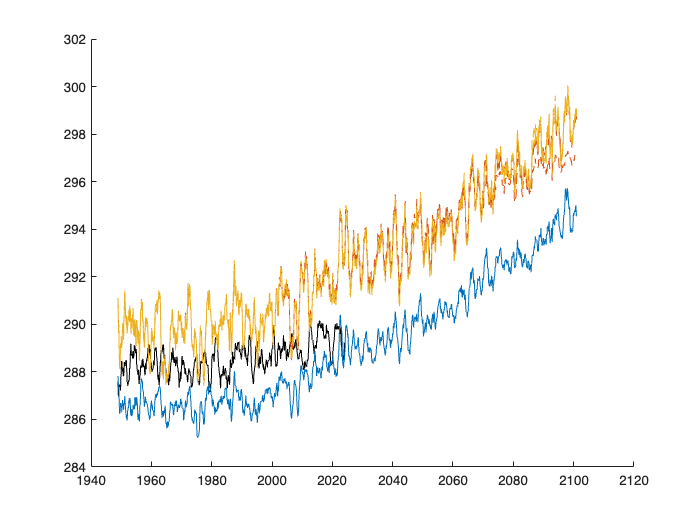

yr_obs = 1948+1/24 : 1/12 : 2024-1/24;
yr_mod = 1948+1/24 : 1/12 : 2101-1/24;
color = lines(7);
% figure; hold on; 
% plot(yr_obs, movmean(reshape(mean(obs(:,:,:,9:end), [1,2]),[],1), [11,0], 'endpoints', 'fill'), 'k');
% plot(yr_mod, movmean(reshape(mean(mod_cp(:,:,:,49:end), [1,2]),[],1), [11,0], 'endpoints', 'fill'), 'color', color(1,:));
% plot(yr_mod, movmean(reshape(mean(mhat_cp_qm, [1,2]),[],1), [11,0], 'endpoints', 'fill'), 'color', color(2,:));
% plot(yr_mod, movmean(reshape(mean(mhat_cp_qdm, [1,2]),[],1), [11,0], 'endpoints', 'fill'), 'color', color(3,:));
% plot(yr_mod, movmean(QM_series, [11,0], 'endpoints', 'fill'), '--', 'color', color(2,:));
% plot(yr_mod, movmean(QDM_series, [11,0], 'endpoints', 'fill'), '--', 'color', color(3,:));

% WUS mean time series comparison, 8 panels, obs, mod (raw), mod (QM), mod
% (QDM)
Varnames{7} = 'mrsos';
nv = 9;
[yy, xx] = meshgrid(lat, lon); wgt = cosd(yy);
% Obs = cell(1, nv); 
% Mod_raw = cell(1, nv); Mod_qm = cell(1, nv); Mod_qdm = cell(1, nv);

for i = 1 : 7%nv
    disp(i);
    % load observation data
    if i == 1 % CPC precipitation
        load('result_240508_01_cpc_input_WUS_1deg_1948-2023.mat', 'pr');
        Obs{i} = reshape(pr(:,:,:,1:75), nlon*nlat, []); % use 1948-1999 data for reference
        mask = mask_pr; 
    elseif i>=2 && i<=6 % ERA5 temperature (max & min), vapor pressure, wind speed, solar radiation
        if i==2, load('result_240508_01_era5_input_WUS_1deg_1940-2023.mat', 'vars'); end
        mask = mask_pr;
        Obs{i} = reshape(vars{i-1}(:,:,:,9:83), nlon*nlat, []); % use 1948-1999 data for reference
    elseif i==7 % GLDAS column and surface soil moisture
        if i==7, load([folder, 'result_240508_01_gldas_input_WUS_1deg_1948-2023.mat'], 'sm_c', 'sm_s'); end
        mask = mask_sm;
        if i == 7
            Obs{i} = reshape(sm_s, nlon*nlat, []);
        % elseif i == 8
        %     Obs{i} = reshape(sm_c, nlon*nlat, []);
        end
    elseif i==8
        load('era5.mon.pet.1940-2023.CONUS.a4899.mat', 'data');        
        data = (data(1:end-1,:,:) + data(2:end,:,:))/2;
        data = (data(:,1:end-1,:) + data(:,2:end,:))/2;
        data = reshape(data(1:100,1:80,:), 100, 80, 12, []);
        data = data(:,end:-1:1,:,9:83);
        data = squeeze(mean(reshape(data, 4, 25, 4, 20, []), [1,3]));
        Obs{i} = reshape(data, nlon*nlat, []);
        mask = mask_pr;
    elseif i==9
        Obs{i} = Obs{1} - Obs{8};
        mask = mask_pr;
    end
    if i<9
    Obs{i}(~mask(:),:) = nan;
    Obs{i} = sum(Obs{i}(mask(:),:).*wgt(mask(:)), 1)'/sum(wgt(mask(:)));
    end
    % load raw model data
    if i<=7
    load([folder, sprintf('result_240508_01_out1_%s.mat', Varnames{i})]); nMm = sum(nm);
    if i==1, data = data*86400; end % change precipitation unit from kg/m2/s to mm/day
        nMm = size(data, 4);
        data0 = reshape(data, nlon*nlat, 12, [], nMm); 
        data0 = reshape(data0(:,:,49:end,:), nlon*nlat, [], nMm); % only use data since 1948 to match with observation
        Mod_raw{i} = squeeze(nansum(data0 .* wgt(:) .* mask(:), 1) ./ sum(~isnan(data0) .* wgt(:) .* mask(:), 1));
    elseif i==8
        load([folder, 'result_240515_01_out1_pet.mat']); nMm = sum(nm);
        nMm = size(data, 4);
        data0 = reshape(data, nlon*nlat, 12, [], nMm); 
        data0 = reshape(data0(:,:,1:end,:), nlon*nlat, [], nMm); % only use data since 1948 to match with observation
        Mod_raw{i} = squeeze(nansum(data0 .* wgt(:) .* mask(:), 1) ./ sum(~isnan(data0) .* wgt(:) .* mask(:), 1));
    elseif i==9
        Mod_raw{i} = Mod_raw{1} - Mod_raw{8};
    end
    % % load QM model data
    % load([folder, sprintf('result_240514_01_out1_%s_qm.mat', Varnames{i})]);
    % nMm = size(data, 4);
    % data0 = reshape(data, nlon*nlat, [], nMm); 
    % Mod_qm{i} = squeeze(nansum(data0 .* wgt(:) .* mask(:), 1) ./ sum(~isnan(data0) .* wgt(:) .* mask(:), 1));

    % load QDM model data
    if i<=7
        load([folder, sprintf('result_240514_01_out1_%s_qdm.mat', Varnames{i})]);
        nMm = size(data, 4);
        data0 = reshape(data, nlon*nlat, [], nMm); 
        Mod_qdm{i} = squeeze(nansum(data0 .* wgt(:) .* mask(:), 1) ./ sum(~isnan(data0) .* wgt(:) .* mask(:), 1));
    elseif i==8
        load([folder, 'result_240515_01_out1_pet-qdm.mat']);
        nMm = size(data, 4);
        data0 = reshape(data, nlon*nlat, [], nMm); 
        Mod_qdm{i} = squeeze(nansum(data0 .* wgt(:) .* mask(:), 1) ./ sum(~isnan(data0) .* wgt(:) .* mask(:), 1));
    elseif i==9
        Mod_qdm{i} = Mod_qdm{1} - Mod_qdm{8};
    end
end

     9



load([folder, 'result_240515_01_out1_pet-qdm.mat'], 'mwgt'); w1 = mwgt;
load([folder, 'result_240514_01_out1_mrsos_qdm.mat'], 'mwgt'); w2 = mwgt;
Mwgt = {w1,w1,w1,w1,w1,w1,w2,w1,w1};
tiles = [25, 75, 2.5, 97.5]/100;
Mod_raw_tl = nan(12*153,4,nv); Mod_qdm_tl = Mod_raw_tl; Mod_qm_tl = Mod_raw_tl;
for i = 1 : nv
    tmp = repmat(Mwgt{i},12*153,1);    
    Mod_raw_tl(:,:,i) = iosr.statistics.quantile(Mod_raw{i}, tiles, 2, 'r-5', tmp);
    Mod_qdm_tl(:,:,i) = iosr.statistics.quantile(Mod_qdm{i}, tiles, 2, 'r-5', tmp);
    % Mod_qm_tl(:,:,i) = iosr.statistics.quantile(Mod_qm{i}, tiles, 2, 'r-5', tmp);
end
Mod_raw_tl = movmean(Mod_raw_tl, [11,0], 'includenan', 'endpoints', 'fill');
Mod_qdm_tl = movmean(Mod_qdm_tl, [11,0], 'includenan', 'endpoints', 'fill');
% Mod_qm_tl = movmean(Mod_qm_tl, [11,0], 'includenan', 'endpoints', 'fill');

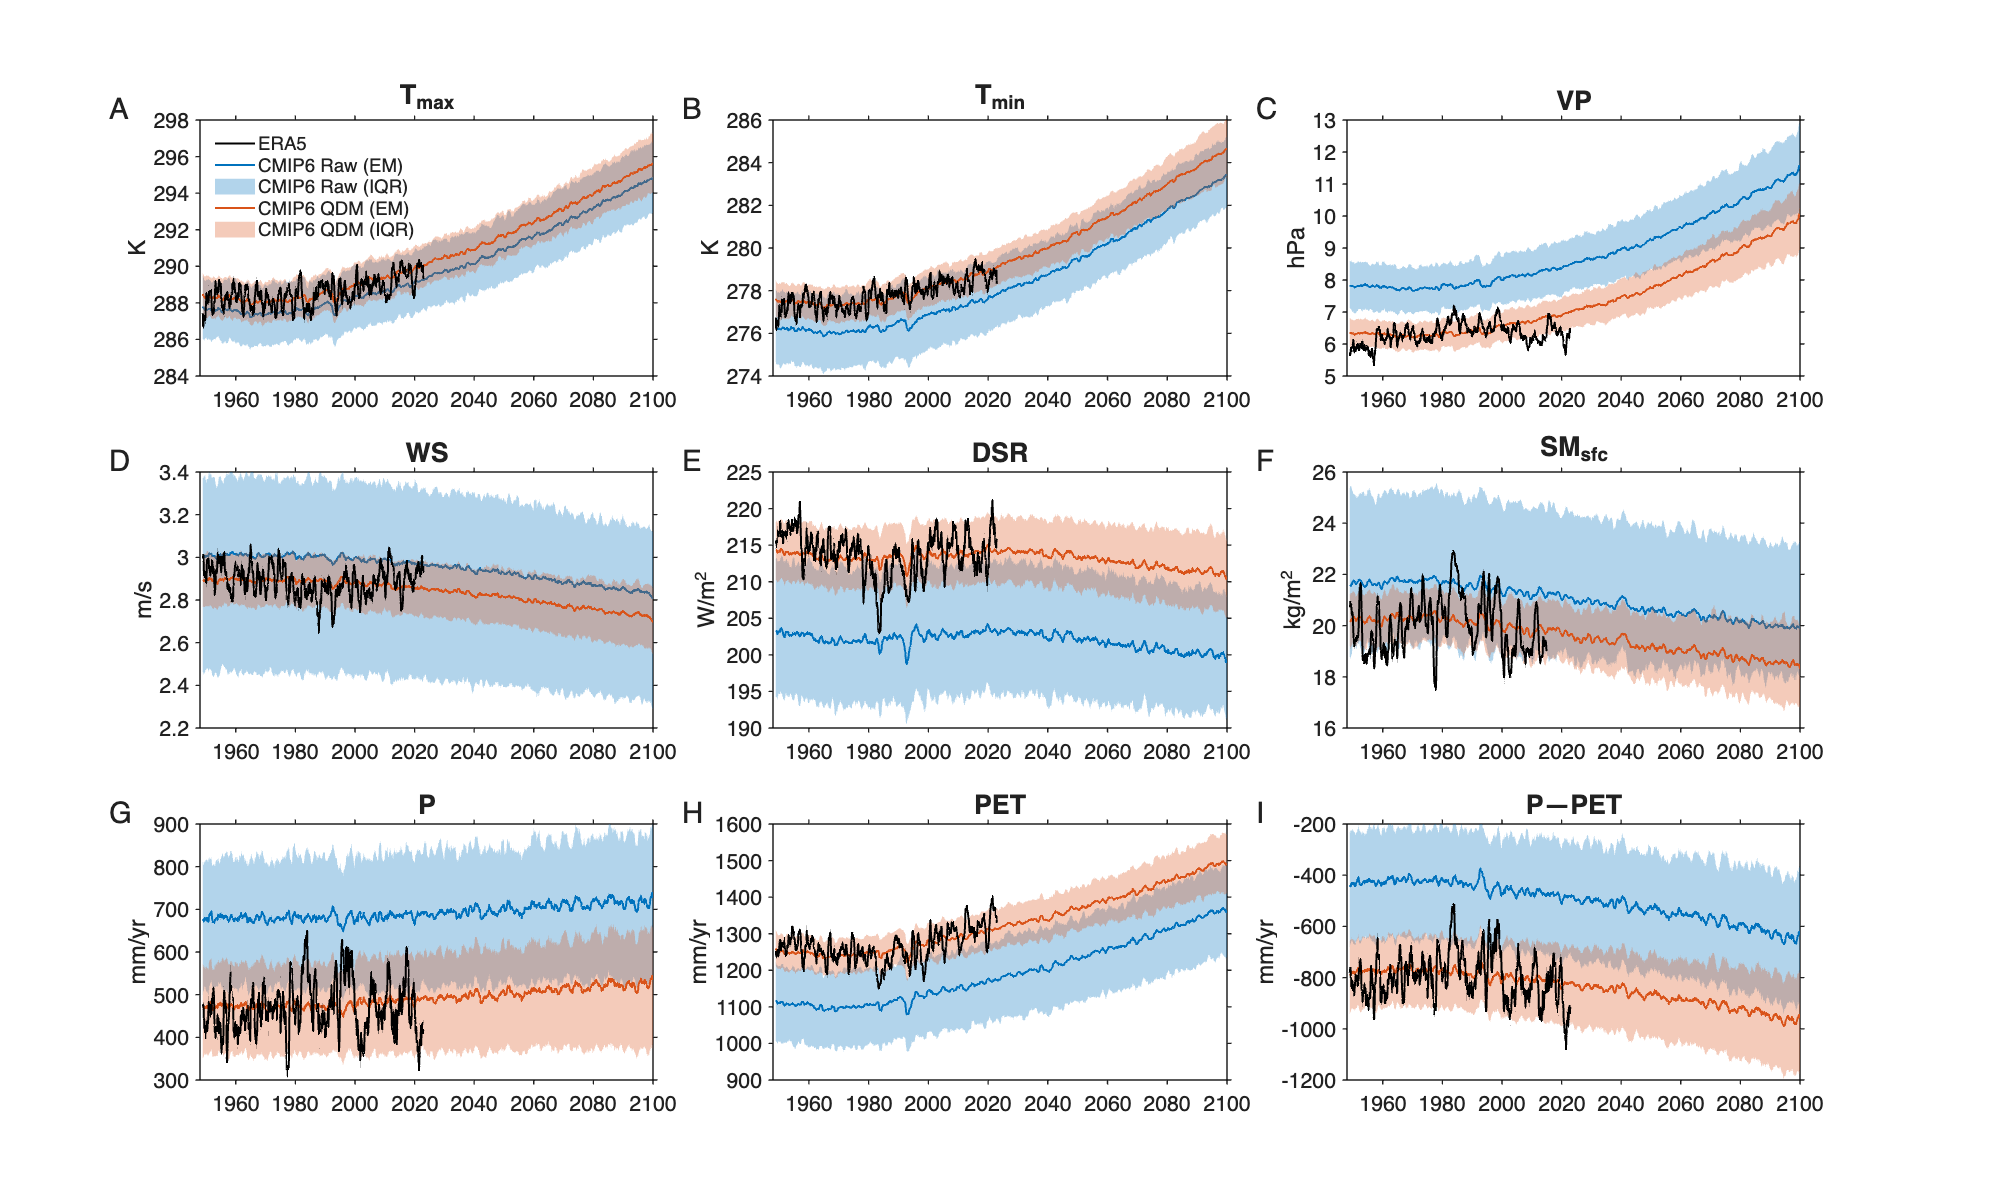

color = lines(7);
tO1 = 1948+1/24 : 1/12 : 2023-1/24;
tO2 = 1948+1/24 : 1/12 : 2015-1/24;
tM = 1948+1/24 : 1/12 : 2101-1/24;
fa = 0.3;
tts = {'P', 'T_{max}', 'T_{min}', 'VP', 'WS', 'DSR', 'SM_{sfc}', 'PET', 'P—PET'};
units = {'mm/yr', 'K', 'K', 'hPa', 'm/s', 'W/m^2', 'kg/m^2', 'mm/yr', 'mm/yr'};
ylims = {[300,900], [284,298], [274,286], [5,13], [2.2,3.4], [190,225], [16,26], [900,1600], [-1200,-200]};
yts = {300:100:900, 284:2:298, 274:2:286, 5:13, 2.2:0.2:3.4, 190:5:225, 16:2:26, 900:100:1600, -1200:200:-200};
% units = {'mm/d', '°C', '°C', 'hPa', 'm/s', 'W/m^2'};
F0 = @(x) x; F1 = @(x) x-273.15; F2 = @(x) x/100; F3 = @(x) x*365;
% Funit = {F0, F1, F1, F2, F0, F0};
Funit = {F3, F0, F0, F2, F0, F0, F0, F3, F3};
fig = figure;
set(fig, 'Visible', 'on');
k = [7,1:6,8,9];%[1,3,5,2,4,6];
for i = 1 : nv
    % load([folder, sprintf('result_240508_01_out1_%s.mat', Varnames{i})], 'mwgt'); Mwgt{i} = mwgt;
    subaxis(3, 3, k(i), 'sv', 0.08, 'sh', 0.06); hold on;
    % if i <= 6, tO = tO1; else tO = tO2; end
    if i==7, tO = tO2; else tO = tO1; end
    [hl(2), hl(3)] = plotWithShade(tM, getMovEnsembleMean(Funit{i}(Mod_raw{i}), Mwgt{i}), Funit{i}(Mod_raw_tl(:,1:2,i)), color(1,:), fa);
    [hl(4), hl(5)] = plotWithShade(tM, getMovEnsembleMean(Funit{i}(Mod_qdm{i}), Mwgt{i}), Funit{i}(Mod_qdm_tl(:,1:2,i)), color(2,:), fa);
    % plotWithShade(tM, getMovEnsembleMean(Mod_qm{i}, Mwgt{i}), Mod_qm_tl(:,1:2,i), color(3,:), 0.2);
    hl(1) = plotWithShade(tO, getMovEnsembleMean(Funit{i}(Obs{i}), 1), [], 'k', 1);
    title(tts{i}); ylabel(units{i});
    if i == 2
        legend(hl, {'ERA5', 'CMIP6 Raw (EM)', 'CMIP6 Raw (IQR)', ...
            'CMIP6 QDM (EM)', 'CMIP6 QDM (IQR)'}, 'location', 'northwest'); 
    end
    set(gca, 'xlim', [1948,2100], 'xtick', 1960:20:2100, 'xticklabelrotation', 0, ...
        'ylim', ylims{i}, 'ytick', yts{i}, 'tickdir', 'out');
    z_add_letter_title(gca, char(64+k(i)), [0.20, -0.05])
end
set_style(gcf); 
set(gcf, 'position', [0,0,2000,1200])

% exportgraphics(fig, 'paper8_sfig_cmip6_bias_correction_mean.jpg', 'Resolution', 300);

size(getMovEnsembleMean(Funit{i}(Obs{i}), 1))

ans =    900     1


size(tO)

ans =      1   804


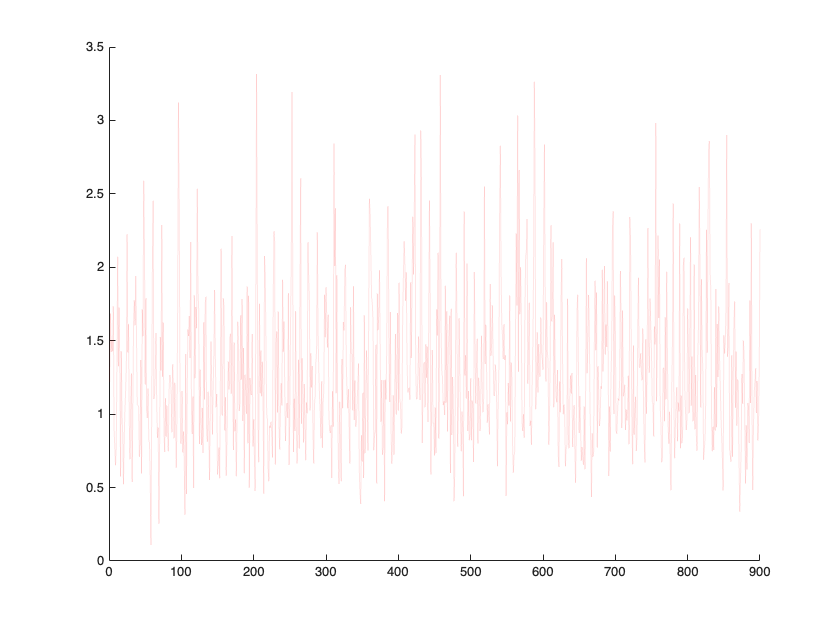


figure;
% patch('XData', [(1:length(Obs{1}))'; NaN], 'YData', [Obs{1}; NaN], 'EdgeColor', [0 0.5 0.8 0.1], 'LineWidth', 2);
lineAlphaFcn = @(x,y,color,alpha) patch('XData',[x(:);nan],'YData',[y(:);nan],'EdgeColor',color,'EdgeAlpha',0.1);
lineAlphaFcn(1:length(Obs{1}), Obs{1}, [1,0,0], 0.1)


function [hl, hf] = plotWithShade(x, y, y_lu, c, fa)
    % Validate the inputs
    if length(x) ~= length(y)
        error('The inputs x, y, and e must have the same length.');
    end
    x = x(:); y = y(:); %y_l = y_l(:); y_u = y_u(:);
    ind = ~isnan(y);
    % Fill the area between y_upper and y_lower
    if ~isempty(y_lu) 
        if size(y_lu,2) == 2
            hf = fill([x(ind); flipud(x(ind))], [y_lu(ind,1); flipud(y_lu(ind,2))], c, 'EdgeColor', 'none', 'FaceAlpha', fa);
        elseif size(y_lu,2) == 4
            hf(1) = fill([x(ind); flipud(x(ind))], [y_lu(ind,3); flipud(y_lu(ind,4))], c, 'EdgeColor', 'none', 'FaceAlpha', fa(2));
            hf(2) = fill([x(ind); flipud(x(ind))], [y_lu(ind,1); flipud(y_lu(ind,2))], c, 'EdgeColor', 'none', 'FaceAlpha', fa(1));
        end
    end
    % Plot the main line
    hl = plot(x, y, '-', 'color', c, 'LineWidth', 1.5); % Blue line with a thickness of 1.5
end
function xm = getMovEnsembleMean(x, w)
xm = movmean(nansum(x .* w, 2) ./ sum(~isnan(x) .* w,2), [11,0], 'includenan', 'endpoints', 'fill');
end